%ER_7.0 calculations and outputs

%Aero related
drag_coeff     = 0.584;
front_area     = 0.7590;

%VD related
CG_height              = 310;
front_axle             = 800;
rear_axle              = 775;
roll_resist            = 0.02;
tire_b                 = 10;
tire_c                 = 1.9;
tire_d                 = 1 ;
tire_e                 = 0.97;
tire_dia               = 18;
tire_inertia           = 0.001;
vehicle_mass           = 220;
rider_mass             = 60;

%Powertrain related
gear_ratio             = 2.267;

%To run the simulink file
sim('ER_7.slx')

%To Extract values from the simulation
Speed = Speed.signals.values;
Torque = Torque.signals.values;
Time = tout;

%Max speed, torque and Time of simulation
Ms = max(Speed)

Ms = 79.8282

Mt = max(Torque)

Mt = 129.2340

Simul_time = max(Time)

Simul_time = 250



%plotting values

[Ms, indexMax] = max(Speed)

Ms = 79.8282

indexMax = 154

Timax = Time(indexMax)

Timax = 250

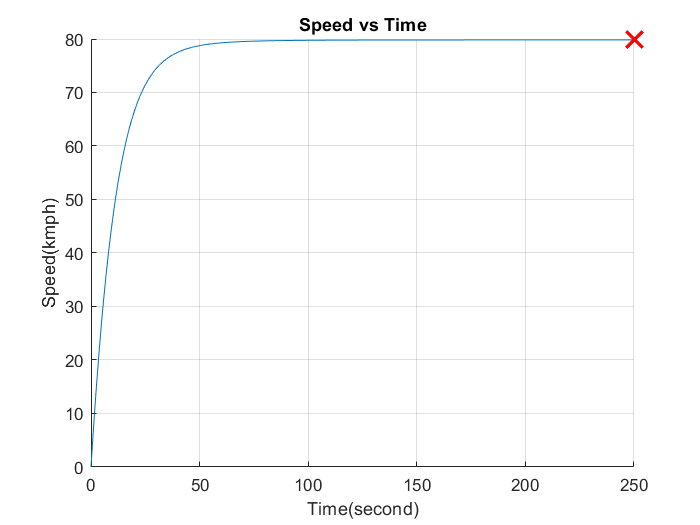


figure 
hold on
plot(Time,Speed)
plot(Timax,Ms,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Time(second)')
ylabel('Speed(kmph)')
grid on
title('Speed vs Time')


[Mt, indexMax] = max(Torque)

Mt = 129.2340

indexMax = 41

Timax = Time(indexMax)

Timax = 0.0072

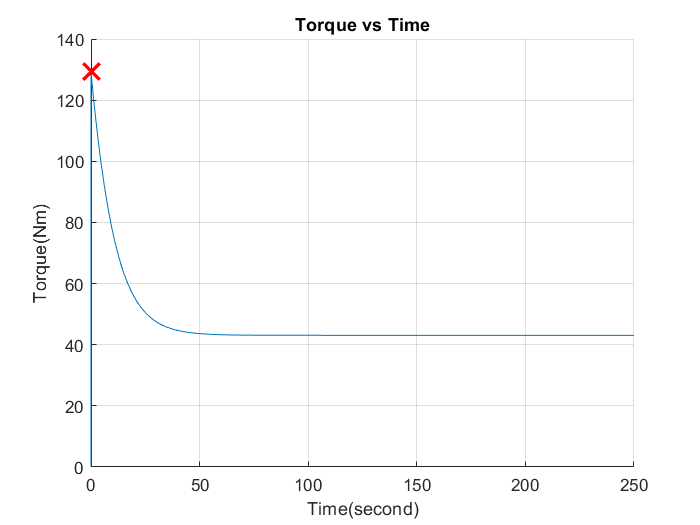


figure
hold on
plot(Time,Torque)
plot(Timax,Mt,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Time(second)')
ylabel('Torque(Nm)')
grid on
title('Torque vs Time')


[Mt , indexMax] = max(Torque)

Mt = 129.2340

indexMax = 41

Smax = Speed(indexMax)

Smax = 0.0419

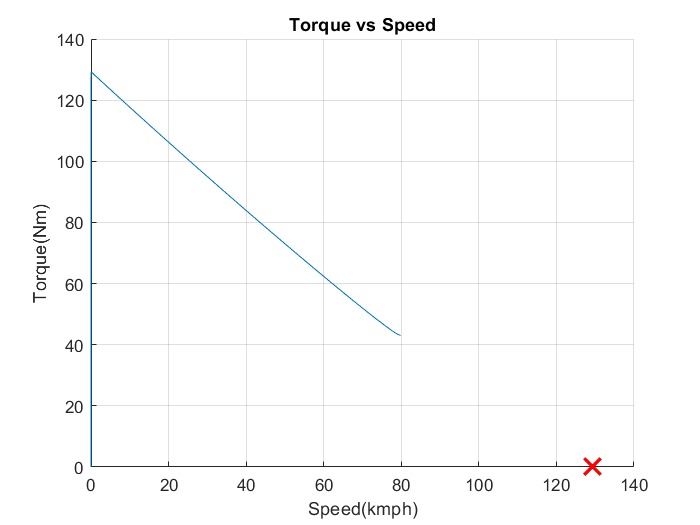


figure
hold on
plot(Speed,Torque)
plot(Mt ,Smax,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Speed(kmph)')
ylabel('Torque(Nm)')
grid on
title('Torque vs Speed')